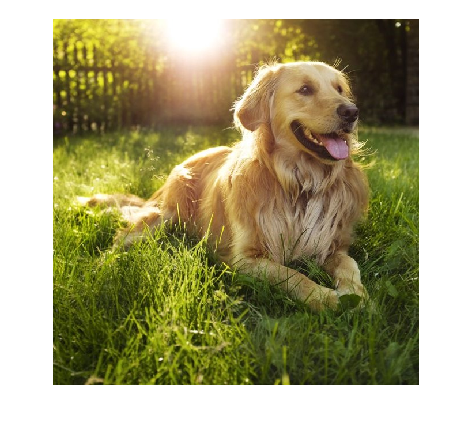

img = imread("squaredog.jpg");
imshow(img);

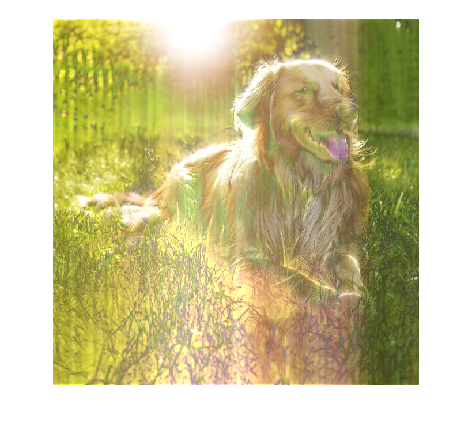


R = double(img(:,:,1));
G = double(img(:,:,2));
B = double(img(:,:,3));

%%COSE CON LOGARITMO

% dpws = log2(R);
% tpwsc = dpws/log2(3);
% imagesc(dpws)
% imagesc(tpws)
% R = (ones(size(R))*2).^dpws;

% R = log(255./R)
% R = rescale(R,1,255)
% R = (1./R)
% R = rescale(R,1,255)

%% COSE CON TRASFORMATA
% RR = fwht(R);
% RR(200:end,1:end) = 0;
% imshow(RR);
% colormap("gray")
% RR = ifwht(RR);
% RR = imcrop(RR,[0 0 635 635]);
% RR= rescale(RR,0,1);

for i = 1: size(R,1)
    R(:,i) = envelope(R(:,i),200,'analytic');
    G(:,i) = envelope(G(:,i),200,'analytic');
    B(:,i) = envelope(B(:,i),200,'analytic');
end
imshow(uint8(cat(3,R,G,B)));


%imshow(uint8(R.*RR));
%imshow(RR)



